# Spot diagram

*Aberrations* in an optical system cause light to not converge on a single point. The optical system of a model eye is subject to aberrations, as is the biological eye.

One way to characterize the aberration in an optical system is with a spot diagram. Rays from a point in object space are directed so that they evenly fill the entrance window. If the optical system were free of aberrations, then these rays should all converge at a single point on the retina. A plot of the dispersion of these points in space is a spot diagram.

Here we examine the spot diagram for an accommodated model eye. This simulation reveals a limitation of the current model in describing the optics of the actual human eye. The quadric surfaces used to describe the refractive surface of the eye are subject to larger spherical aberrations than is true of the actual biology. The spot diagram generated here has a radius of roughly 100 μm, which is about an order of magnitude larger than the performance of the actual optics of the eye.

## Create the model eye

We examine an eye for a particular wavelength, accommodated to a point at a particular distance, and with a particular size of the aperture stop.

spectralDomain = 555;
accommodation = 3;
stopRadius = 2;
eye = modelEyeParameters('spectralDomain',spectralDomain,'accommodation',accommodation);

## Select a position in object space

We need to pick a location in object space that is the source of the rays that will create the spot diagram. The example here is for a point that is on the longitudinal axis of the eye (i.e., field position `[0, 0]`). This field position is defined with respect to reference positions that are derived from properties of the eye.

fieldAngularPosition = [0 0];
angleReferenceCoord = eye.landmarks.incidentNode.coords;
rayOriginDistance = 1000/accommodation;
distanceReferenceCoord = calcPrincipalPoint(eye);

## Ray trace

We use the function `calcRayBundleFromField` to direct a set of rays towards the boundary of the entrance window. Over a loop we vary the size of the aperture stop so that we can examine a set of rays organized into rings from the outer perimeter of the entrance pupil towards the center. 

% Define the denisty with which we will fill the entrance window
nRings = 6;
nPoints = 36;

% Set up some variables for the loop
scale = linspace(0,1,nRings+1);
scale = scale(2:end);
rayPaths = {};

% Set up a figure for the spot diagram
figure

% Loop over the rings
for rr = 1:nRings
    
    % The stop radius and number of points for this ring
    nStopPerimPoints = round(nPoints .* scale(rr));
    thisRadius = stopRadius * scale(rr);

    % Ray trace
    [retinaPoints,tempPaths] = calcRayBundleFromField(eye,fieldAngularPosition,thisRadius,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord,nStopPerimPoints);
    
    % Extract the location of points where they hit the cornea
    corneaPoints = cell2mat(cellfun(@(x) x(:,2),tempPaths,'UniformOutput',false));
    
    % Add the corneal and retinal points to the spot diagram
    subplot(2,1,1); plot(corneaPoints(2,:),corneaPoints(3,:),'*'); hold on
    subplot(2,1,2); plot(retinaPoints(2,:),retinaPoints(3,:),'*'); hold on

    % Store the rayPaths for later plotting
    rayPaths = [rayPaths, tempPaths];

end

% Clean up the spot diagram
subplot(2,1,1); axis equal; title('incident rays'); ylabel('vertical [mm]'); xlabel('horizontal [mm]')
subplot(2,1,2); axis equal; title('retina points'); ylabel('vertical [mm]'); xlabel('horizontal [mm]')

The spot diagram at the retina reveals two sorts of aberrations. First, there is spherical aberration, which causes the inner rings to be closely overlapping, while the outer rings are progressively distant. Second, there is astigmatism, which causes the points to be more dispersed horizontally than vertically.

We can compare the dispersion of points in the spot diagram to the diffraction limit of the optical system. Even if the system were free of optical aberrations, there would still be spread of the points at the retina due to the effect of diffraction on light, arising principally at the aperture stop of the optical system. The ray-tracing routines used in the software do not model the effects of interference and diffraction. We can, however, characterize the effect of diffraction by calclating the size of the Airy disk, which is the theoretical spread of light rays that results from an aperture stop of a given size (and for a given wavelength of light and f-number of an optical system). This next step computes the Airy disk radius and adds it to the spot diagram.

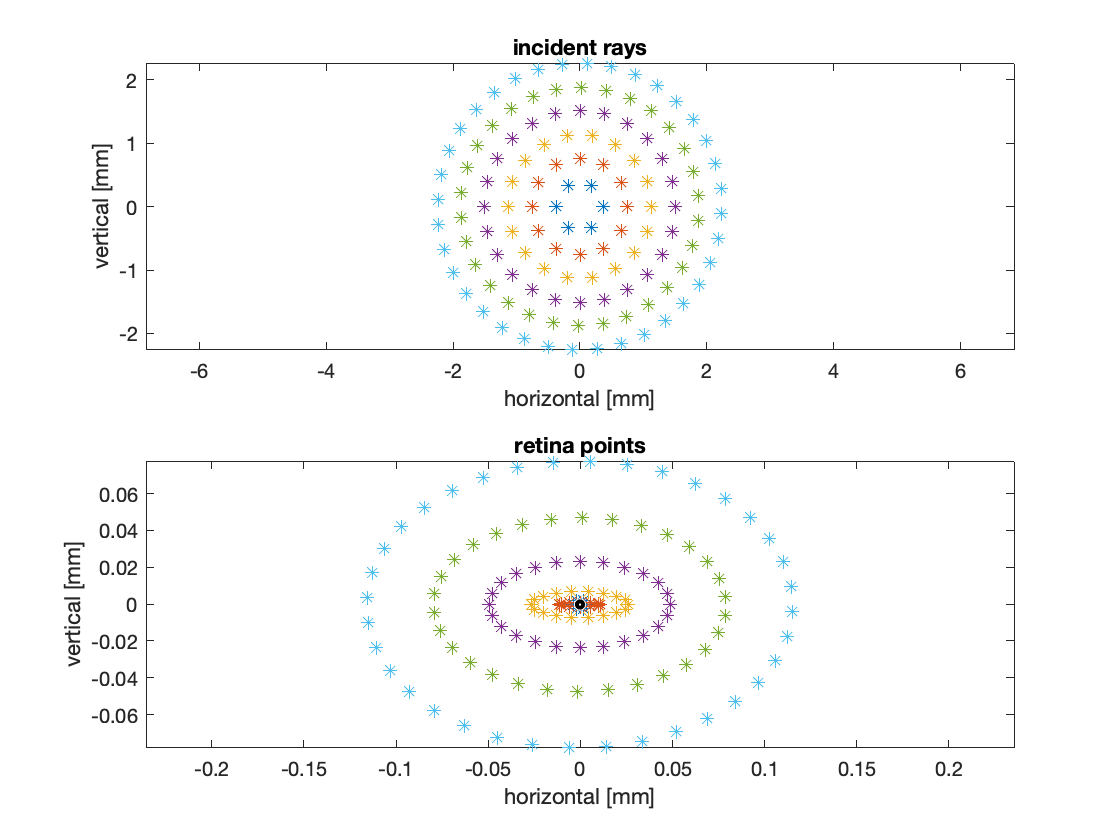

airyDiskRadius = calcAiryDiskRadius(eye,stopRadius);
spotDiagramCenter = [mean(retinaPoints(2,:)), mean(retinaPoints(3,:))];
subplot(2,1,2); viscircles(spotDiagramCenter,airyDiskRadius,'Color','k');

There is a trade off between the aberration of the system and the diffraction limit. The smaller the stop radius, the smaller the aberration, but the larger the Airy disk will be. Try adjusting the size of ther aperture stop to try and find the spot diagram that is closest to the diffraction limit of the system.

## System plot

The code below creates a 3D rendering of the eye and the rays used to compute the spot diagram.

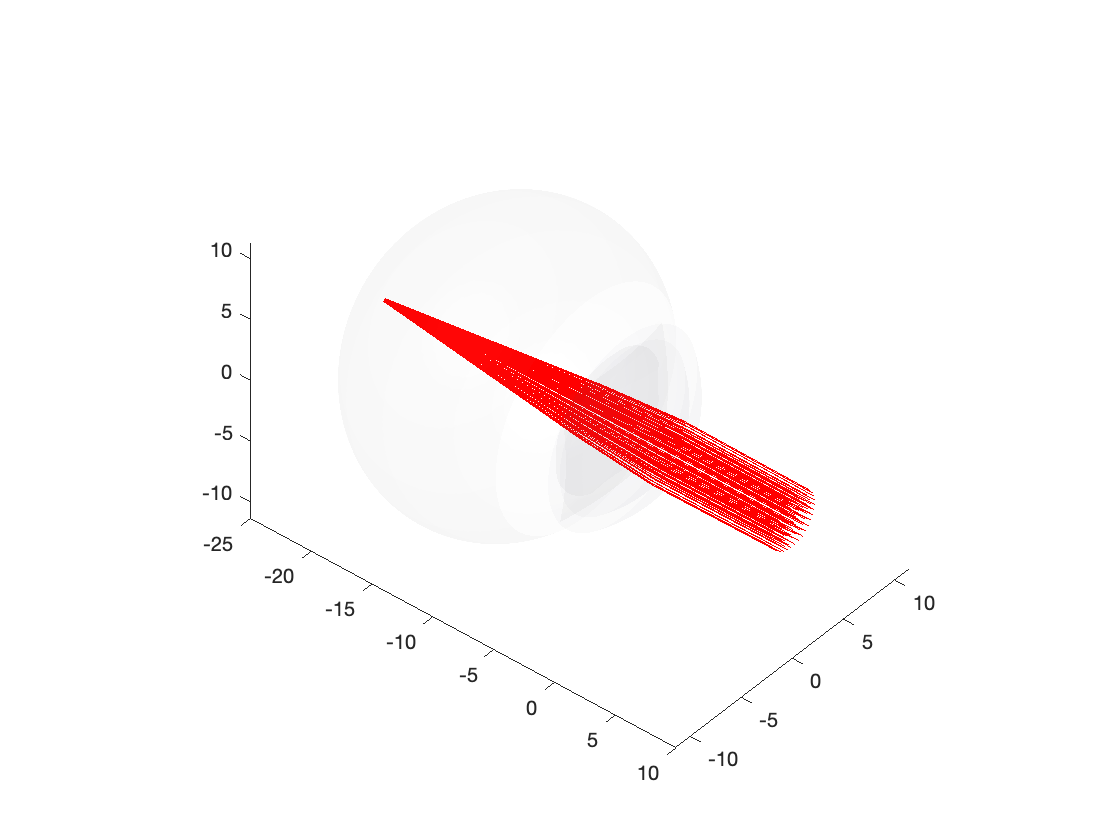

figure
plotOpticalSystem(eye,'newFigure',false,'surfaceAlpha', 0.05);
% Add the rays to the plot
for ii=1:length(rayPaths)
    plotOpticalSystem('newFigure',false,'rayPath',rayPaths{ii});
end
xlim([-25 10]);